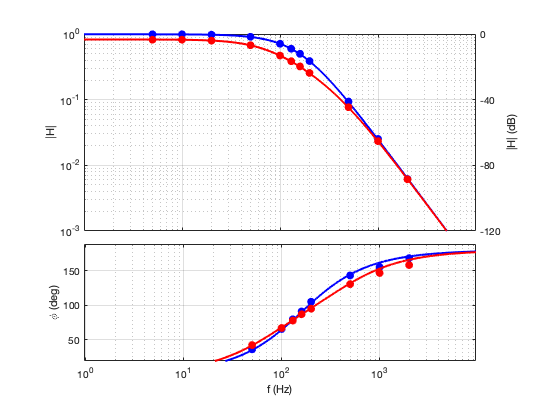

a = 1

addpath("routine/")
Vpp=3;
R=1e5;
C=1e-8;
tau=R*C;
f3dB=1/(2*pi*tau);
%modello
f=linspace(1,1e5,1e5)';
w=2*pi*f;
G=(1./(1-1i*w*tau)).^2;

grafici = 1;

if grafici==1
    fig_1 = bode_plot(f,G, 'col', 'b','add_dB');
end
%dati
freq=         [5    10    20    50    100    130    160    200    500    1e3    2e3]';
V_in=         [3    3     3     2.98  3      2.99   2.98   3      3      3      3]';
dV_in= 0.5e-3*[37.5 37    37.5  50    40     43     43     43     31     43     43]';
V_out=        [3    3     2.96  2.73  2.15   1.8    1.5    1.17   0.282  0.0757 0.0185]';
dV_out=0.5e-3*[43   56    43    50    56     43     56     22     10     0.0095 0.01]';
dt=      1e-3*[2.7  2.36  2.18  2     1.82   1.7    1.58   1.46   0.796  0.432  0.234]';

H= V_out./V_in;
phi= dt.*freq(1:length(dt),1)*2*pi;
if grafici==1
    fig_2 = bode_plot(freq(1:length(dt),1), [H phi], 'points','.','col','b','fig',fig_1);
end

%%doppio RC
R=1e5;
C=1e-8;
tau=R*C;
f3dB=1/(2*pi*tau);
%modello
R_osc=1e6;
C_osc=100e-12;
f=linspace(1,1e5,1e5)';
w=2*pi*f;
Z_eq= R./(1-1i*w*tau);
Z=R_osc./(1-1i*w*R_osc*(C+C_osc));
G=Z.*Z_eq./(R*(Z_eq+R+Z));
if grafici == 1
    fig_3 = bode_plot(f,G, 'col', 'r','add_dB','r','fig',fig_2);
end
%dati
freq=         [5    10    20    50    100    130    160    200    500    1e3    2e3]';
V_in=         [3    3     3     2.98  3      2.99   2.98   3      3      3      3]';
dV_in= 0.5e-3*[37.5 37    37.5  50    40     43     43     43     31     43     43]';
V_out=        [2.48 2.48  2.4   2.03  1.42   1.16   .962   .77    .231   .07    .0183]';
dV_out=0.5e-3*[50   50    50    43    30     30     30     30     30     20     14]';
dt=      1e-3*[3    2.82  2.6   2.34  1.86   1.66   1.51   1.32   .726   .408   .22]';

H= V_out./V_in;
phi= dt.*freq(1:length(dt),1)*2*pi;
if grafici == 1
    a=1
    bode_plot(freq(1:length(dt),1), [H phi], 'points','.','col','r','fig',fig_3);
end

%%risposta impulsionale impulso di 5V a 100 Hz e 10 us per tempi <<tau:  in 1 ms arriva a 36 mV, variando width cambia
%%massimo ma resta sempre a tau. con impulso più largo la magia finisce
f=50;
A= 5;
offset=2.5;
width=10e-6;
%dati
t=1e-6*[];
V=1e-3*[];
